First, follow the installation instructions in README.md and add mesolf code folder to path, including all subfolders.

Set MesoLF parameters

workdir = pwd();  % change to desired working directory
if ~exist(workdir, 'dir')
    mkdir(workdir);
end
SIin = struct;
SIin.indir = [workdir filesep() 'raw'];
SIin.outdir = [workdir filesep() 'mesolf'];
SIin.frames_start = 1;
SIin.frames_step = 1;
SIin.frameRate = 18;
SIin.frames_average = false;
SIin.frames_x_offset = 924.7;
SIin.frames_y_offset = 459.3;
SIin.frames_dx = 16.68;
SIin.frames_crop_border_microlenses = [1 1 1 1];
SIin.mask_file = false;  % don't mask out anything, all is valid
SIin.patch_mode = 'carpet';
SIin.n_patches = [1 2];  % 1 x 2 tiles
SIin.psffile = fullfile(workdir, 'PSFmatrix_lfm2pram_M10_FN12p5_pm200_from-200_to200_zspacing4_Nnum15_lambda520_OSR3.mat');  % will be downloaded in next section
SIin.gpu_ids = [1];  % select high-performance GPU here; indices start at 1 (so, add one to the gpu indices reported by nvidia-smi, which start at 0)
SIin.filt_method = 'cnn';

Configure the parallel pool here

%% Prepare parallel pool
cluster = parcluster('local');
cluster.NumWorkers = floor(feature('numcores') / 4);
cluster.NumThreads = 4;
job_storage_location = tempname();
mkdir(job_storage_location);
cluster.JobStorageLocation = job_storage_location;
disp(cluster);
delete(gcp('nocreate'));
pool = parpool(cluster, 'IdleTimeout', 600); %#ok<NASGU>

Download & unzip PSF file (3.3 GB) and raw data (17.5 GB). Demo dataset are two tiles (sub-ROIs) of the data shown in Fig. 2a (0-200 um depth range)

psf_fullpath = websave(SIin.psffile, ...
    'https://zenodo.org/record/7306113/files/PSFmatrix_lfm2pram_M10_FN12p5_pm200_from-200_to200_zspacing4_Nnum15_lambda520_OSR3.mat?download=1');
rawzip_fullpath = websave(fullfile(workdir, 'mesolf_demo_dset.zip'), ...
    'https://zenodo.org/record/7306113/files/mesolf_demo_dset.zip?download=1');
unzip(rawzip_fullpath, SIin.indir);

Run MesoLF

2021-07-27 15:24:46: Starting MesoLF with arguments:
                             indir: '/data1/tmp/raw'
                            outdir: '/data1/tmp/mesolf'
                           psffile: '/data1/tmp/PSFmatrix_lfm2pram_M10_FN12p5_pm200_from-200_to200_zspacing4_Nnum15_lambda520_OSR3.mat'
                   frames_x_offset: 924.7000
                   frames_y_offset: 459.3000
                         frames_dx: 16.6800
                      frames_start: 1
                       frames_step: 1
                        frames_end: Inf
                    frames_average: 0
                         frameRate: 18
                     psf_cache_dir: '/dev/shm'
                           gpu_ids: 1
    frames_crop_border_microlenses: [1 1 1 1]
                         mask_file: 0
                         worker_ix: 0
                        patch_mode: 'carpet'
                         n_patches: [1 2]
                          ROI_list: []
                    ROI_patch_size: []
   

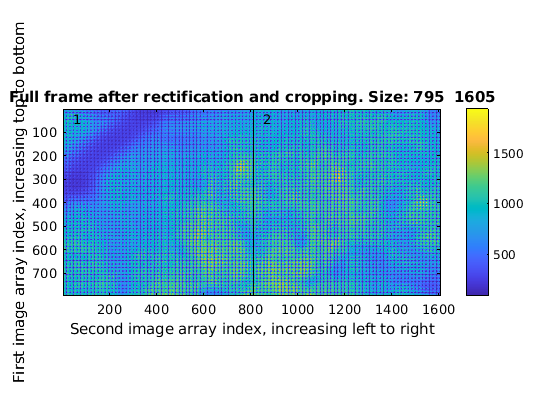

{"location":[[1,1],[795,810]],"size":[795,810],"raw_cut":[[11,907],[26,939]],"raw_cut_xCenter":448.13599999999997,"raw_cut_yCenter":448.13599999999997}
{"location":[[1,811],[795,1605]],"size":[795,795],"raw_cut":[[11,907],[926,1823]],"raw_cut_xCenter":448.13599999999997,"raw_cut_yCenter":448.13599999999997}
 Local Cluster

    Properties: 

                   Profile: local
                  Modified: true
                      Host: v-gpu2
                NumWorkers: 6
                NumThreads: 4

        JobStorageLocation: /tmp/tpdc37dcda_3be1_4482_aee4_be8558b737dd
   RequiresOnlineLicensing: false

    

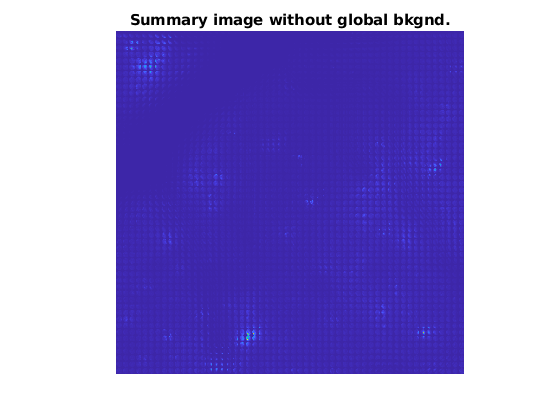

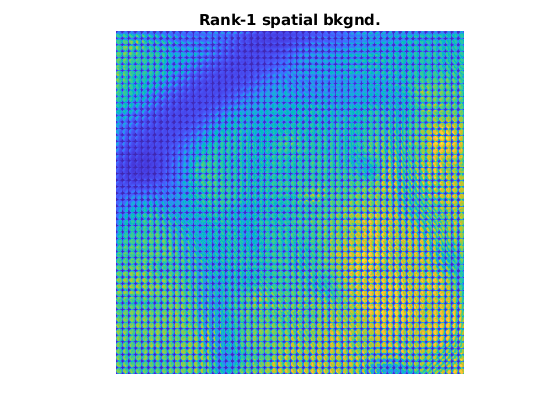

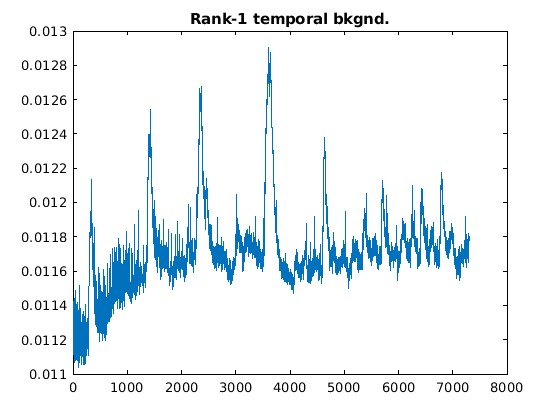

2021-07-27 15:30:04: Starting reconstruction
3D reconstruction
iter 1 | 3, phase-space deconvolution took 106.2593 secs
iter 2 | 3, phase-space deconvolution took 105.8316 secs
iter 3 | 3, phase-space deconvolution took 105.639 secs
The file was saved successfully. Elapsed time : 0.448 s.
2021-07-27 15:36:25: Starting segmentation
segment for depth 1 


100 neurons have been detected
segment for depth 2 


100 neurons have been detected
segment for depth 3 


100 neurons have been detected
segment for depth 4 


100 neurons have been detected
stopped because of a warning regarding matrix inversion
segment for depth 5 


stopped because of a warning regarding matrix inversion
stopped because of a warning regarding matrix inversion
100 neurons have been detected
segment for depth 6 


100 neurons have been detected
segment for depth 7 


100 neurons have been detected
segment for depth 8 


100 neurons have been detected
segment for depth 9 


100 neurons have been detected
segment for depth 10 


100 neurons have been detected
segment for depth 11 


stopped because of a warning regarding matrix inversion
100 neurons have been detected
stopped because of a warning regarding matrix inversion
segment for depth 12 


100 neurons have been detected
segment for depth 13 


100 neurons have been detected
segment for depth 14 


100 neurons have been detected
segment for depth 15 


100 neurons have been detected
segment for depth 16 


100 neurons have been detected
segment for depth 17 


100 neurons have been detected
segment for depth 18 


100 neurons have been detected
segment for depth 19 


100 neurons have been detected
segment for depth 20 


100 neurons have been detected
segment for depth 21 


100 neurons have been detected
segment for depth 22 


100 neurons have been detected
segment for depth 23 


stopped because of a warning regarding matrix inversion
stopped because of a warning regarding matrix inversion
100 neurons have been detected
stopped because of a warning regarding matrix inversion
segment for depth 24 


100 neurons have been detected
segment for depth 25 


100 neurons have been detected
stopped because of a warning regarding matrix inversion
segment for depth 26 


100 neurons have been detected
segment for depth 27 


100 neurons have been detected
segment for depth 28 


100 neurons have been detected
segment for depth 29 


100 neurons have been detected
segment for depth 30 


100 neurons have been detected
segment for depth 31 


100 neurons have been detected
segment for depth 32 


100 neurons have been detected
segment for depth 33 


100 neurons have been detected
segment for depth 34 


100 neurons have been detected
segment for depth 35 


100 neurons have been detected
segment for depth 36 


100 neurons have been detected
segment for depth 37 


100 neurons have been detected
segment for depth 38 


100 neurons have been detected
segment for depth 39 


100 neurons have been detected
segment for depth 40 


100 neurons have been detected
segment for depth 41 


100 neurons have been detected
segment for depth 42 


100 neurons have been detected
segment for depth 43 


100 neurons have been detected
segment for depth 44 


100 neurons have been detected
segment for depth 45 


100 neurons have been detected
segment for depth 46 


100 neurons have been detected
segment for depth 47 


100 neurons have been detected
segment for depth 48 


100 neurons have been detected
segment for depth 49 


100 neurons have been detected
segment for depth 50 


100 neurons have been detected
segment for depth 51 


100 neurons have been detected
The file was saved successfully. Elapsed time : 0.205 s.
The file was saved successfully. Elapsed time : 0.175 s.
The file was saved successfully. Elapsed time : 0.190 s.
Cluster segments
Compute linkage tree and cut
Merge valid segments 100%    [..........] done
2021-07-27 15:39:17: Starting library generation
Building forward components
	 build component No.1...  
	 build component No.2...  
	 build component No.3...  
	 build component No.4...  
	 build component No.5...  
	 build component No.6...  
	 build component No.7...  
	 build component No.8...  
	 build component No.9...  
	 build component No.10...  
	 build component No.11...  
	 build component No.12...  
	 build component No.13...  
	 build component No.14...  
	 build component No.15...  
	 build component No.16...  
	 build component No.17...  
	 build component No.18...  
	 build component No.19...  
	 build component No.20...  
	 build component No.21...  
	 build component No.22...  

2021-07-27 16:21:50: Starting main demixing
MesoLF main iteration 1/5
MesoLF main iteration 2/5
MesoLF main iteration 3/5
MesoLF main iteration 4/5
MesoLF main iteration 5/5
Elapsed time is 46.594284 seconds.
2021-07-27 16:51:14: Starting component refinement


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200

i = 201

i = 202

i = 203

i = 204

i = 205

i = 206

i = 207

i = 208

i = 209

i = 210

i = 211

i = 212

i = 213

i = 214

i = 215

i = 216

i = 217

i = 218

i = 219

i = 220

i = 221

i = 222

i = 223

i = 224

i = 225

i = 226

i = 227

i = 228

i = 229

i = 230

i = 231

i = 232

i = 233

i = 234

i = 235

i = 236

i = 237

i = 238

i = 239

i = 240

i = 241

i = 242

i = 243

i = 244

i = 245

i = 246

i = 247

i = 248

i = 249

i = 250

i = 251

i = 252

i = 253

i = 254

i = 255

i = 256

i = 257

i = 258

i = 259

i = 260

i = 261

i = 262

i = 263

i = 264

i = 265

i = 266

i = 267

i = 268

i = 269

i = 270

i = 271

i = 272

i = 273

i = 274

i = 275

i = 276

i = 277

i = 278

i = 279

i = 280

i = 281

i = 282

i = 283

i = 284

i = 285

i = 286

i = 287

i = 288

i = 289

i = 290

i = 291

i = 292

i = 293

i = 294

i = 295

i = 296

i = 297

i = 298

i = 299

i = 300

i = 301

i = 302

i = 303

i = 304

i = 305

i = 306

i = 307

i = 308

i = 309

i = 310

i = 311

i = 312

i = 313

i = 314

i = 315

i = 316

i = 317

i = 318

i = 319

i = 320

i = 321

i = 322

i = 323

i = 324

i = 325

i = 326

i = 327

i = 328

i = 329

i = 330

i = 331

i = 332

i = 333

i = 334

i = 335

i = 336

i = 337

i = 338

i = 339

i = 340

i = 341

i = 342

i = 343

i = 344

i = 345

i = 346

i = 347

i = 348

i = 349

i = 350

i = 351

i = 352

i = 353

i = 354

i = 355

i = 356

i = 357

i = 358

i = 359

i = 360

i = 361

i = 362

i = 363

i = 364

i = 365

i = 366

i = 367

i = 368

i = 369

i = 370

i = 371

i = 372

i = 373

i = 374

i = 375

i = 376

i = 377

i = 378

i = 379

i = 380

i = 381

i = 382

i = 383

i = 384

i = 385

i = 386

i = 387

i = 388

i = 389

i = 390

i = 391

i = 392

i = 393

i = 394

i = 395

i = 396

i = 397

i = 398

i = 399

i = 400

i = 401

i = 402

i = 403

i = 404

i = 405

i = 406

i = 407

i = 408

i = 409

i = 410

i = 411

i = 412

i = 413

i = 414

i = 415

i = 416

i = 417

i = 418

i = 419

i = 420

i = 421

i = 422

i = 423

i = 424

i = 425

i = 426

i = 427

i = 428

i = 429

i = 430

i = 431

i = 432

i = 433

i = 434

i = 435

i = 436

i = 437

i = 438

i = 439

i = 440

i = 441

i = 442

i = 443

i = 444

i = 445

i = 446

i = 447

i = 448

i = 449

i = 450

i = 451

i = 452

i = 453

i = 454

i = 455

i = 456

i = 457

i = 458

i = 459

i = 460

i = 461

i = 462

i = 463

i = 464

i = 465

i = 466

i = 467

i = 468

i = 469

i = 470

i = 471

i = 472

i = 473

i = 474

i = 475

i = 476

i = 477

i = 478

i = 479

i = 480

i = 481

i = 482

i = 483

i = 484

i = 485

i = 486

i = 487

i = 488

i = 489

i = 490

i = 491

i = 492

i = 493

i = 494

i = 495

i = 496

i = 497

i = 498

i = 499

i = 500

i = 501

i = 502

i = 503

i = 504

i = 505

i = 506

i = 507

i = 508

i = 509

i = 510

i = 511

i = 512

i = 513

i = 514

i = 515

i = 516

i = 517

i = 518

i = 519

i = 520

i = 521

i = 522

i = 523

i = 524

i = 525

i = 526

i = 527

i = 528

i = 529

i = 530

i = 531

2021-07-27 17:20:56: Starting with patch 2/2
2021-07-27 17:20:56: Loading and rectifying input frames
Reading frames: 
1/7301 (img_000001.tif) 26/7301 (img_000026.tif) 51/7301 (img_000051.tif) 76/7301 (img_000076.tif) 101/7301 (img_000101.tif) 
126/7301 (img_000126.tif) 151/7301 (img_000151.tif) 176/7301 (img_000176.tif) 201/7301 (img_000201.tif) 226/7301 (img_000226.tif) 
251/7301 (img_000251.tif) 276/7301 (img_000276.tif) 301/7301 (img_000301.tif) 326/7301 (img_000326.tif) 351/7301 (img_000351.tif) 
376/7301 (img_000376.tif) 401/7301 (img_000401.tif) 426/7301 (img_000426.tif) 451/7301 (img_000451.tif) 476/7301 (img_000476.tif) 
501/7301 (img_000501.tif) 526/7301 (img_000526.tif) 551/7301 (img_000551.tif) 576/7301 (img_000576.tif) 601/7301 (img_000601.tif) 
626/7301 (img_000626.tif) 651/7301 (img_000651.tif) 676/7301 (img_000676.tif) 701/7301 (img_000701.tif) 726/7301 (img_000726.tif) 
751/7301 (img_000751.tif) 776/7301 (img_000776.tif) 801/7301 (img_000801.tif) 826/7301 (img_000826.t

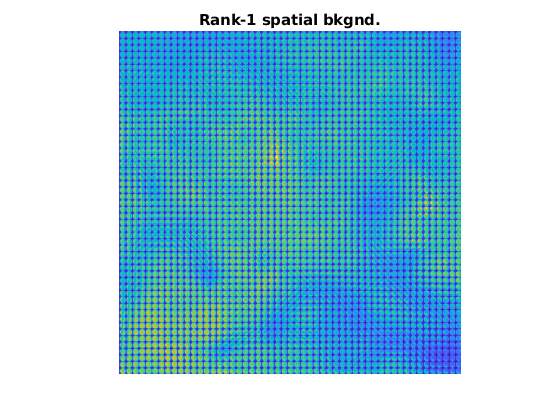

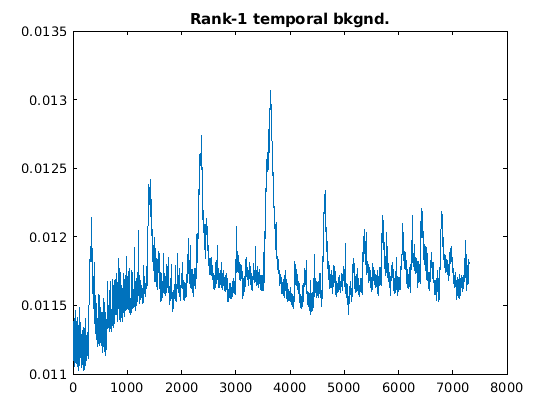

2021-07-27 17:24:21: Starting reconstruction
3D reconstruction
iter 1 | 3, phase-space deconvolution took 52.4875 secs
iter 2 | 3, phase-space deconvolution took 51.7303 secs
iter 3 | 3, phase-space deconvolution took 51.7636 secs
The file was saved successfully. Elapsed time : 0.171 s.
2021-07-27 17:27:34: Starting segmentation
segment for depth 1 


segment for depth 2 


segment for depth 3 


segment for depth 4 


segment for depth 5 


segment for depth 6 


segment for depth 7 


segment for depth 8 


segment for depth 9 


segment for depth 10 


segment for depth 11 


stopped because of a warning regarding matrix inversion
segment for depth 12 


segment for depth 13 


segment for depth 14 


segment for depth 15 


segment for depth 16 


segment for depth 17 


segment for depth 18 


segment for depth 19 


segment for depth 20 


100 neurons have been detected
segment for depth 21 


segment for depth 22 


segment for depth 23 


segment for depth 24 


segment for depth 25 


segment for depth 26 


segment for depth 27 


segment for depth 28 


segment for depth 29 


segment for depth 30 


segment for depth 31 


segment for depth 32 


segment for depth 33 


segment for depth 34 


segment for depth 35 


segment for depth 36 


segment for depth 37 


segment for depth 38 


segment for depth 39 


100 neurons have been detected
segment for depth 40 


100 neurons have been detected
segment for depth 41 


100 neurons have been detected
segment for depth 42 


100 neurons have been detected
segment for depth 43 


stopped because of a warning regarding matrix inversion
100 neurons have been detected
segment for depth 44 


100 neurons have been detected
segment for depth 45 


100 neurons have been detected
segment for depth 46 


100 neurons have been detected
stopped because of a warning regarding matrix inversion
segment for depth 47 


100 neurons have been detected
segment for depth 48 


100 neurons have been detected
segment for depth 49 


100 neurons have been detected
segment for depth 50 


100 neurons have been detected
segment for depth 51 


The file was saved successfully. Elapsed time : 0.176 s.
The file was saved successfully. Elapsed time : 0.159 s.
The file was saved successfully. Elapsed time : 0.156 s.
Cluster segments
Compute linkage tree and cut
Merge valid segments 100%    [..........] done
2021-07-27 17:29:52: Starting library generation
Building forward components
	 build component No.1...  
	 build component No.2...  
	 build component No.3...  
	 build component No.4...  
	 build component No.5...  
	 build component No.6...  
	 build component No.7...  
	 build component No.8...  
	 build component No.9...  
	 build component No.10...  
	 build component No.11...  
	 build component No.12...  
	 build component No.13...  
	 build component No.14...  
	 build component No.15...  
	 build component No.16...  
	 build component No.17...  
	 build component No.18...  
	 build component No.19...  
	 build component No.20...  
	 build component No.21...  
	 build component No.22...  
	 build component No.23...  
	

2021-07-27 17:48:22: Starting main demixing
MesoLF main iteration 1/5
MesoLF main iteration 2/5
MesoLF main iteration 3/5
MesoLF main iteration 4/5
MesoLF main iteration 5/5
Elapsed time is 22.424814 seconds.
2021-07-27 17:54:58: Starting component refinement


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200

i = 201

i = 202

i = 203

i = 204

i = 205

i = 206

i = 207

i = 208

i = 209

i = 210

i = 211

i = 212

i = 213

i = 214

i = 215

i = 216

i = 217

i = 218

i = 219

i = 220

i = 221

i = 222

i = 223

i = 224

i = 225

i = 226

i = 227

i = 228

i = 229

i = 230

i = 231

i = 232

i = 233

i = 234

i = 235

i = 236

i = 237

i = 238

i = 239

i = 240

2021-07-27 18:10:23: Starting patch merging
Patch index: 1
Patch index: 2
2021-07-27 18:10:34: Starting trace quality classification


Plot neuron 3D positions


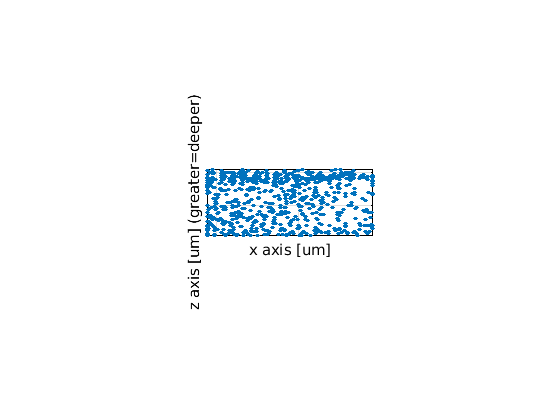

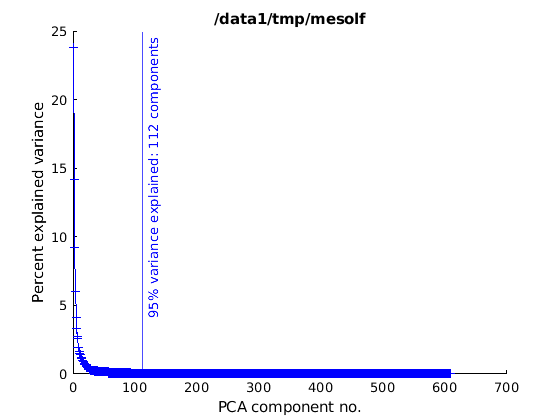

Total no. of neurons pre filtering:		764 
Total no. of neurons post filtering:		610 
No. of PCA components required to explain 95 precent of variance:		112 
[xmin xmax dx] (mm, pre filter):		0.026	0.505	0.479
[ymin ymax dz] (mm, pre filter):		0.026	1.045	1.019
[zmin zmax] (um, pre filter):		   8.8	 202.4
2021-07-27 18:11:20 Returning with exit code 0


tic;
mesolf(SIin);

toc  % elapsed time: 1012 seconds

Elapsed time is 1007.775479 seconds.


Expected output can be downloaded here:

[https://zenodo.org/record/7306113/files/mesolf_demo_dset_output.zip?download=1](https://zenodo.org/record/7306113/files/mesolf_demo_dset_output.zip?download=1) (500 MB)

Load MesoLF final result for inspection

SO = load(fullfile(SIin.outdir, 'after_filter_final_temporal_result.mat'));

Estimate SNR of neuronal traces, fit baseline, normalize to noise level

traces = SO.global_T_filtered;
noise_std = [];
pp = [];
baseline = [];
noise = zeros(size(traces));
traces_filt = zeros(size(traces));
baseline_ts = zeros(size(traces));
traces_prctlfilt = zeros(size(traces));
for k = 1 : size(traces,1)
    if mod(k, 100) == 0
        fprintf('%i ', k);
    end
    trace = traces(k, :);
    hh = fft([trace flip(trace)]);
    hh(2 : 7) = 0;
    hh(end-5 : end) = 0;
    hh = ifft(hh);
    trace = hh(1 : length(hh)/2);
    
    %trace = zscore(trace);
    noise(k,:) = smooth(trace, 5)' - trace;
    noise_std(k) = std(noise(k,:));
    %baseline(k) = prctile(smooth(traces_hipass(k, :), 8), 25);
    traces_prctlfilt(k,:) = running_percentile(traces(k,:), 100, 5)';
    baseline_ts(k,:) = sgolayfilt(traces_prctlfilt(k,:), 4, 401);
    pp(k) = (max(smooth(trace)) - min(smooth(trace))) / noise_std(k);
    traces_filt(k, :) = trace;
end

100 200 300 400 500 600 

[~, n] = sort(-pp);
SO.snr_sort_ixs = n;
SO.snrs = pp;
SO.ts_noisenorm = (traces - baseline_ts) ./ (noise_std');

Fit each SNR-scaled trace with the "foopsie" auto-regressive model

First, find good values for g and lam by inspection of fit to highest-SNR trace

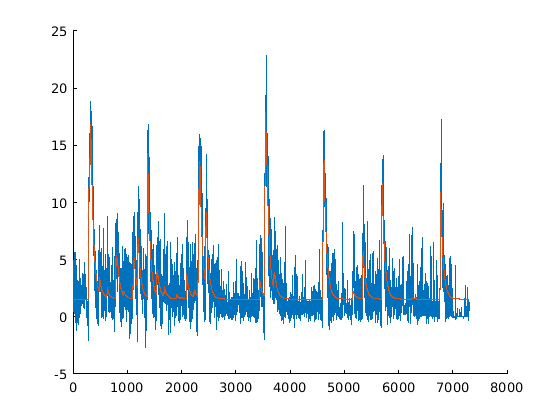

SO.ts_noisenorm_snrsort = SO.ts_noisenorm(SO.snr_sort_ixs, :);
y = SO.ts_noisenorm(1, :);

g = 0.97;  % Parameter of the AR(1) process that models the fluorescence. Higher is slower
lam = 50;  % sparsity
optimize_b = true;
optimize_g = 5;
[c, s, b, g, ~] = foopsi_oasisAR1(y, g, lam, optimize_b, optimize_g);

figure;
hold on;
plot(y);
plot(c + b);
hold off;

Next, fit all traces with fixed g and lam, but re-optimize baseline

for i=1:size(SO.ts_noisenorm,1)
    if mod(i, 100) == 0
        fprintf('%i ', i);
    end
    y = SO.ts_noisenorm(i, :);
    optimize_b = true;
    optimize_g = 0;
    [c, s, b, g, ~] = foopsi_oasisAR1(y, g, lam, optimize_b, optimize_g);
    SO.ts_noisenorm_c(i,:) = c;
    SO.ts_noisenorm_s(i,:) = s;
    SO.ts_noisenorm_b(i) = b;
end

100 200 300 400 500 600 

Stacked line plot of raw and denoised traces, showing top 100 traces in SNR

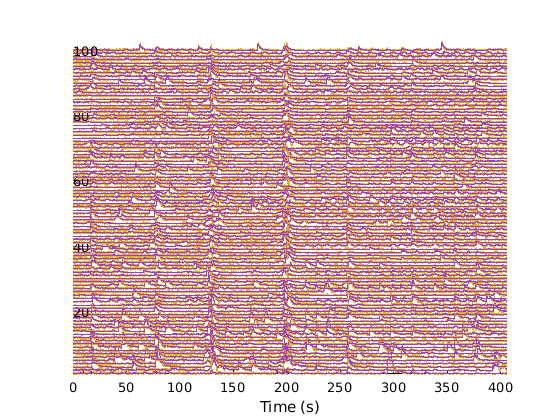

sel_t = 1:size(SO.ts_noisenorm,2);
ts = SO.ts_noisenorm(:, sel_t);
ts_dn = bsxfun(@plus, SO.ts_noisenorm_c, SO.ts_noisenorm_b');
t0 = 0;
t1 = size(ts,2) / SIin.frameRate;
frames = (t0 * SIin.frameRate) + 1 : t1 * SIin.frameRate;
ts = ts(:, frames);
ts_dn = ts_dn(:, frames);

y_shift = 0.9 * abs(prctile(ts(:), 99.0));
sel = SO.snr_sort_ixs;
s0 = 1;
s1 = 100;
sel = sel(s0:s1);
nixs = 1:size(ts,1);
sel_nixs = nixs(sel);

h = 278/360;
s = 0.7;
hsv_dn = [h s .8; h s .8; h s .8; h s .8; h s .8];
h = 42/360;
s = .83;
hsv = [h s .9; h s .9; h s .9; h s .9; h s .9];
colororder = hsv2rgb(hsv);
colororder_dn = hsv2rgb(hsv_dn);

figure;
for n_ix = 1:numel(sel_nixs)
    if n_ix == 1
        hold on
    end
    ax = gca();
    loop_ts = ts(sel_nixs(n_ix),:);
    loop_ts_dn = ts_dn(sel_nixs(n_ix),:);
    t = frames / SIin.frameRate;
    plot(t, squeeze(loop_ts) + y_shift*(n_ix-1), 'Color', colororder(mod(n_ix, 5) + 1,:), 'LineWidth', 0.2);
    plot(t, squeeze(loop_ts_dn) + y_shift*(n_ix-1), 'Color', colororder_dn(mod(n_ix, 5) + 1,:), 'LineWidth', 0.4);
    if mod(n_ix, 20) == 0
        text(t0 * 0.9, y_shift*(n_ix-1), num2str(n_ix));
    end
end
line([10 10], [0 10],'Color',[1 0 0]);
xlabel('Time (s)');
ax = gca;
box off;
ax.YAxis.Visible = 'off';   % remove y-axis
xlim([t0 t1]);
ylim([0 y_shift * (numel(sel_nixs) + 5)]);
yticks([]);
hold off;